## Week 10

### Data Access - Part 2

Another common way that data is stored online is simple text data at a given URL. Often times the URL is 'constructed' by a user selecting a number of options (dataset, variable requested, time period, and so on). As an example, let us consider USGS streamflow data. The USGS maintains thousands of stream gauges here:

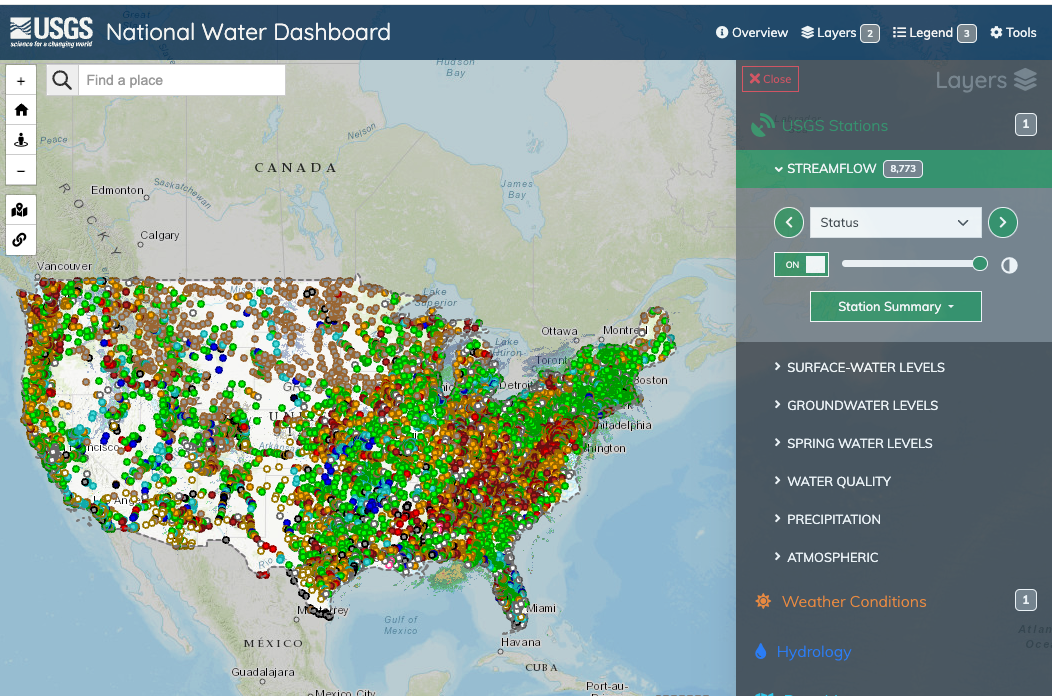

If you zoom in and click on a particular gauge, you will see, by default, 7 days of data, like this:

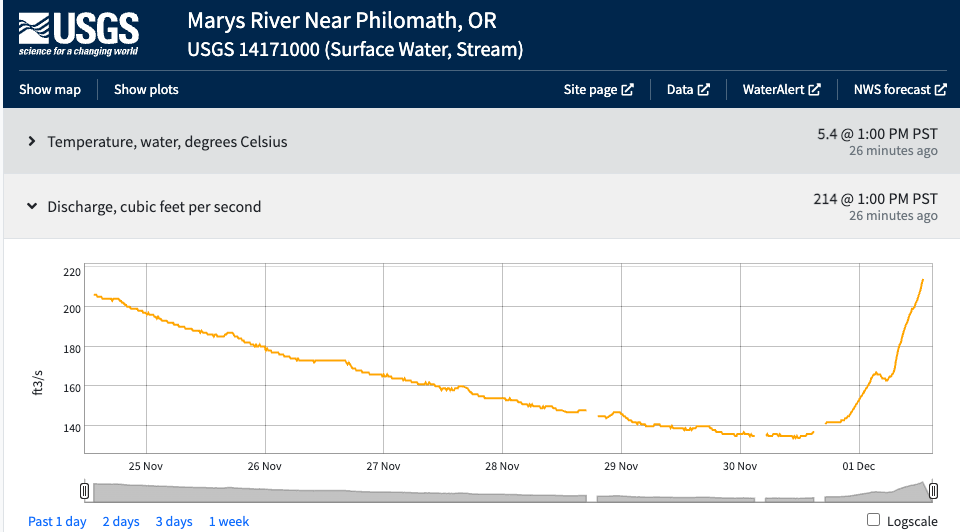And, if you click on 'site page' it will take you to the website for that particular gauge. At that site, you can choose the 'dowload data' option. Before doing that, you can adjust the time span, among other things, to customize your data order.

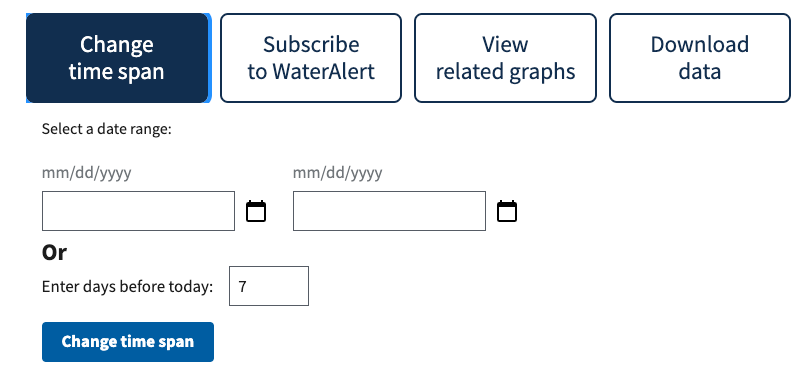

Whew. That will, finally, take you to a page like this.

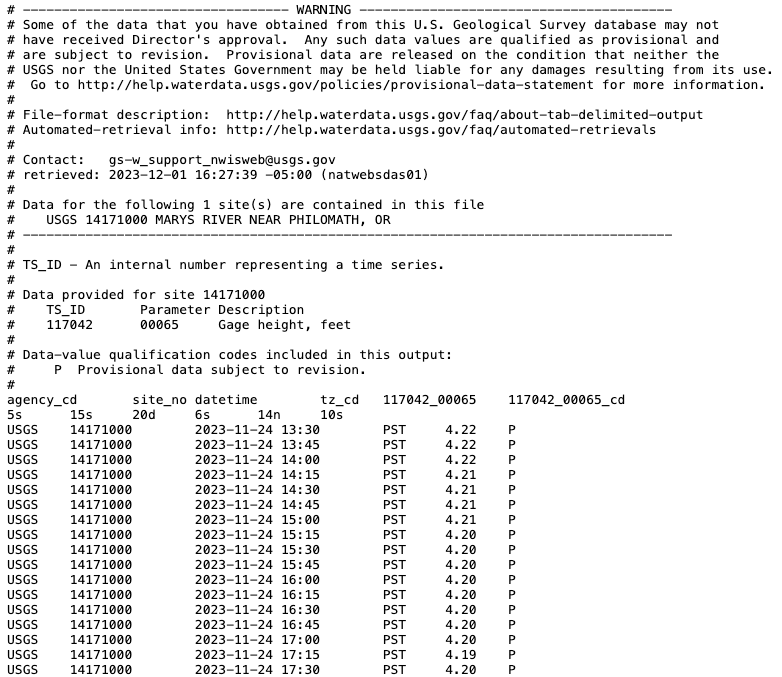

And, in your browser, you can just 'save' the data to a simple text file. So, this is great, but a lot of mousing and clicking, and it is very inefficient.

So, how can we automate this? Well, the URL that gets constructed as you are doing all that mousing is very specific...it contains information about the specific site, the variables requested (streamflow, water temp, other), the time period (one month, a full year, etc.) and the time spacing (hourly, daily, etc.) of the data. So, we can use that to our advantage and we can construct a URL that meets our requirements and then we can have matlab 'scrape' the data from the website and save it to a file for us!

Let's just test this out with an example. Use the following URL

url='https://waterdata.usgs.gov/nwis/dv?format=rdb&period=30&site_no=14171000'

Site 14171000 is the Mary's River near Corvallis. The 'period' you see is set to 30, which means we will just get the last 30 days of data. We could instead change this to a date range if we wanted.

Next let us specify an output file name

fn='/usgs_14171000_daily_20231201.txt'

url = 'https://waterdata.usgs.gov/nwis/dv?format=rdb&period=30&site_no=14171000'

Next, let us specify a destination path (location) for the output file. I will use the present working directory.

pn=pwd

fn = '/usgs_14171000_daily_20231201.txt'

Ok...let's see if this works

[fname,status] = urlwrite(url,[pn,fn])

pn = '/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10'

Ok, let us look at another example. The NRCS maintains a network of snow telemetry (SNOTEL) sites across the western USA. These measure temperature, snow depth, snow water equivalent and more. 

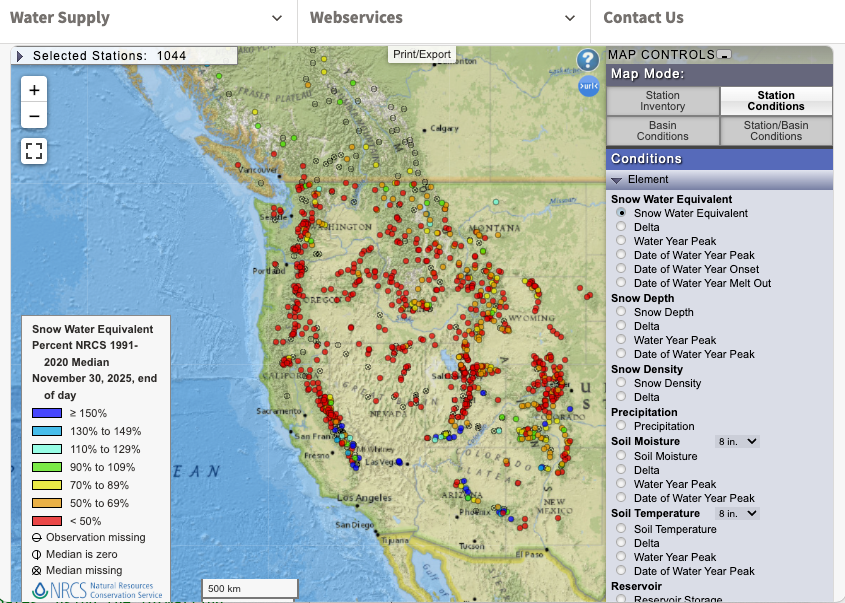

You can click on a station and be taken to graphs, and tables. If you want to generate a 'report' for a custom time period, you can go to [https://wcc.sc.egov.usda.gov/reportGenerator/.](https://wcc.sc.egov.usda.gov/reportGenerator) 

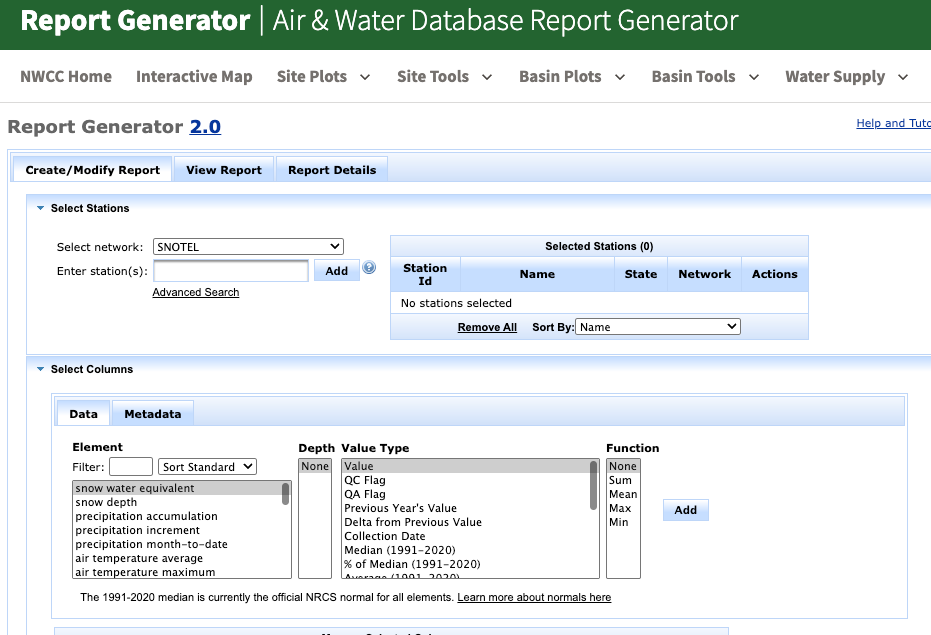

At this website, you can specify a large number of options, and then generate an output file. Great. But tedious...So, below is a function that I wrote that both automates this process, and then also 'parses' the output text file in order to give us a table of useful data. 

outputdata=getsnoteldata(526,'OR','2025-04-01','2025-04-30')

fname = '/Users/dfh/Library/CloudStorage/Box-Box/Hill_Sync/Teaching/Teaching_osu/CE640_OC512/matlab_class/scripts/week10/usgs_14171000_daily_20231201.txt'

status = 1


function Table = getsnoteldata(ID,state,startdate,enddate)

%May 2024. Created by David Hill (dfh@oregonstate.edu). This function will
%return a table of data from a snotel station. The inputs include the ID
%and the state of the station, and start / end dates, using the formatting
%YYYY-MM-DD. State must be two-letter abbreviation in Caps. Dates must be
%char / string format.

outputdata = 30×6 table
    Timestamp     PREC    PRCP    PRCPSA    WTEQ    SNRR
    __________    ____    ____    ______    ____    ____

    2025-04-01    56.3    0.2      0.2      24.2      0 
    2025-04-02    56.5      0        0      24.2    -99 
    2025-04-03    56.5      0        0      24.2    -99 
    2025-04-04    56.5      0        0        24    -99 
    2025-04-05    56.5      0        0      23.8    -99 
    2025-04-06    56.5    0.4      0.4      23.4     50 
    2025-04-07    56.9    0.6        2      23.6    333 
    2025-04-08    57.5    0.5      0.5      25.6     40 
    2025-04-09      58      0        0      25.8    -99 
    2025-04-10      58    0.2      0.2      25.8      0 
    2025-04-11    58.2      0        0      24.7    -99 
    2025-04-12    58.2      0 


%The output table has these columns:
%Timestamp     PREC    PRCP    PRCPSA    WTEQ    SNRR

%first, build up the URLs
url1 = 'https://wcc.sc.egov.usda.gov/reportGenerator/view_csv/customMultiTimeSeriesGroupByStationReport/daily/start_of_period/';
url2 = [num2str(ID),':' state ':SNTL%7Cid=%22%22%7Cname/'];
url3 = [startdate ',' enddate '/']; 
url4 = 'PREC::value,PRCP::value,PRCPSA::value,WTEQ::value,SNRR::value?fitToScreen=false';
url = strcat(url1,url2,url3,url4);

%get data
data=webread(url);

%break up into individual strings.
data=compose(data);
data=splitlines(data);
data(end)=[]; %removes last (empty) row

%Header info
fields={'Timestamp','PREC','PRCP','PRCPSA','WTEQ','SNRR'};

counter=1;
%keep only data lines (eliminate long header)
for j=1:length(data)
    if ~strcmp(data{j}(1),'#')
        if ~strcmp(data{j}(1:4),'Date') %this omits the variables line 
            Data=textscan(data{j},'%D%f%f%f%f%f','Delimiter',',');
            if isempty(Data{6}) %fill in the empty values for SNRR
                Data{6}=-99;
            end
            Table(counter,:)=table(Data{:},'VariableNames',fields);
            counter=counter+1;
        end
    end
end
end

Here is some 'bonus material' for you. Please see my notes below. This will direct you to an amazing GUI (graphical user interface) that allows you to access data from so many different agencies. While the GUI is nice, the codes contained in the distribution are very easy to alter and use for your own purposes. They allow you to download and then PARSE (read in the text files) the data very quickly. It's a gold mine.

% There is one excellent matlab package, developed by the Georgia Coastal
% Ecosystems LTER, that helps to automate the retrieval of data from common
% sources. It is at:

% http://gce-lter.marsci.uga.edu/public/im/tools/toolbox_download.htm
% NOTE: Updated as of 2019...go get the latest!

% 1. Unzip the provided file.
% 2. Enter main folder
% 3. type startup
% 4. Select Data Editor
% 5. File --> Import Data

% 6. Let us try USGS (www)
% 7. Select Oregon
% 8. Select Mary's River and click 'copy' button
% 9. Select Date Range. I chose 1/1/2012 until 12/1/2013.
% 10. Click proceed.
% 11. Adjust column list as desired. ***Click on the various columns. In
% the lower portion of dialog, note the things you can change, including a
% flag option.
% 12. Try tools / plotting / 2dline/symbol. After plot appears, explore
% menu options...tons of ways to customize and export.
% 13. Try file / export / text file.

% Close those windows and try again. Once data editor is open:
% 1. File / Import Data / NCDC
% 2. Select Corvallis State University
% 3. Set date range to be just 2013.
% 4. Explore plots and export as before!
